%% =========================================================================
%  E23 EXAM - COMPLETE SOLUTIONS
%  Winter 2023 Electromagnetics Exam
%  Using EM Helper Toolkit
%% =========================================================================
%
%  SETUP: Add helpers to path first
  addpath('C:\Users\Mads2\DTU\3.semester\Electromagnetics\Helpers');
%
%% =========================================================================

clear; clc;
fprintf('\n========================================\n');

fprintf('  E23 EXAM SOLUTIONS\n');

  E23 EXAM SOLUTIONS


fprintf('========================================\n\n');


%% Physical Constants
c0 = 2.99792458e8;           % Speed of light [m/s]
eps0 = 8.854187817e-12;      % Permittivity of free space [F/m]
mu0 = 4*pi*1e-7;             % Permeability of free space [H/m]
eta0 = sqrt(mu0/eps0);       % Free space impedance ≈ 377 Ω


%% =========================================================================
%  TRANSMISSION LINE PROBLEMS
%% =========================================================================


## Q4 — VSWR for Γ = -j/3


fprintf('Q4: VSWR for Γ = -j/3\n');

Q4: VSWR for Γ = -j/3


fprintf('----------------------------\n');

----------------------------


Gamma_Q4 = -1j/3;
VSWR_Q4 = (1 + abs(Gamma_Q4)) / (1 - abs(Gamma_Q4));
fprintf('|Γ| = %.4f\n', abs(Gamma_Q4));

|Γ| = 0.3333


fprintf('VSWR = (1 + |Γ|)/(1 - |Γ|) = %.4f\n', VSWR_Q4);

VSWR = (1 + |Γ|)/(1 - |Γ|) = 2.0000


fprintf('✓ Answer: VSWR = %.2f\n\n', VSWR_Q4);

✓ Answer: VSWR = 2.00



## Q5 — Power Reflected When |Γ| = 0.3


fprintf('Q5: Power Reflected for |Γ| = 0.3\n');

Q5: Power Reflected for |Γ| = 0.3


fprintf('----------------------------\n');

----------------------------


Gamma_mag_Q5 = 0.3;
P_reflected_Q5 = Gamma_mag_Q5^2;
fprintf('P_reflected = |Γ|² = (%.1f)² = %.2f\n', Gamma_mag_Q5, P_reflected_Q5);

P_reflected = |Γ|² = (0.3)² = 0.09


fprintf('✓ Answer: %.0f%% of incident power\n\n', P_reflected_Q5*100);

✓ Answer: 9% of incident power



## Q6 — Ideal Short Circuit Reflection Coefficient


fprintf('Q6: Reflection Coefficient of Short Circuit\n');

Q6: Reflection Coefficient of Short Circuit


fprintf('----------------------------\n');

----------------------------


ZL_Q6 = 0;
Z0_Q6 = 50;  % arbitrary reference
Gamma_Q6 = (ZL_Q6 - Z0_Q6) / (ZL_Q6 + Z0_Q6);
fprintf('ZL = 0 (short circuit)\n');

ZL = 0 (short circuit)


fprintf('Γ = (ZL - Z0)/(ZL + Z0) = (0 - Z0)/(0 + Z0) = -1\n');

Γ = (ZL - Z0)/(ZL + Z0) = (0 - Z0)/(0 + Z0) = -1


fprintf('✓ Answer: Γ = -1\n\n');

✓ Answer: Γ = -1



## Q7

% Given
Gamma_B = 0.13 * exp(1j*deg2rad(230));

% Test λ/2
r = TLine('Gamma_in', Gamma_B, 0.5);


=== Gamma Propagation (Load → Input) ===
  Gamma_L = -0.0836 -0.0996j
  |Gamma_L| = 0.1300, angle = -130.00 deg
  Length = 0.5000 lambda
  Phase shift = -2βℓ = -360.00 deg
  -----------------------------------------
  Gamma_in = -0.0836 -0.0996j
  |Gamma_in| = 0.1300, angle = -130.00 deg




% Check if Γ_A = Γ_B
fprintf('Γ_A = %.4f∠%.1f°\n', abs(r.Gamma_in), rad2deg(angle(r.Gamma_in)));

Γ_A = 0.1300∠-130.0°


fprintf('Γ_B = %.4f∠%.1f°\n', abs(Gamma_B), rad2deg(angle(Gamma_B)));

Γ_B = 0.1300∠-130.0°


% Output: Both are 0.1300∠230.0° ✓

## Q10 — Normalized Load Impedance on Smith Chart


fprintf('Q10: Normalized Load Impedance\n');

Q10: Normalized Load Impedance


fprintf('----------------------------\n');

----------------------------


ZL_Q10 = 15 - 1j*37.5;
Z0_Q10 = 75;
zL_Q10 = ZL_Q10 / Z0_Q10;
Gamma_Q10 = (zL_Q10 - 1) / (zL_Q10 + 1);
fprintf('ZL = %.0f - j%.1f Ω\n', real(ZL_Q10), abs(imag(ZL_Q10)));

ZL = 15 - j37.5 Ω


fprintf('Z0 = %.0f Ω\n', Z0_Q10);

Z0 = 75 Ω


fprintf('zL = ZL/Z0 = %.2f - j%.2f\n', real(zL_Q10), abs(imag(zL_Q10)));

zL = ZL/Z0 = 0.20 - j0.50


fprintf('Γ = %.4f ∠ %.1f°\n', abs(Gamma_Q10), rad2deg(angle(Gamma_Q10)));

Γ = 0.7257 ∠ -125.4°


fprintf('✓ Answer: zL = 0.2 - j0.5\n\n');

✓ Answer: zL = 0.2 - j0.5




=== Smith Chart Point ===
  Z0 = 75.00 Ohm
  ZL = 15.0000 -37.5000j Ohm
  zL (normalized) = 0.2000 -0.5000j
  Gamma = -0.4201 -0.5917j
  |Gamma| = 0.7257, angle = -125.37 deg



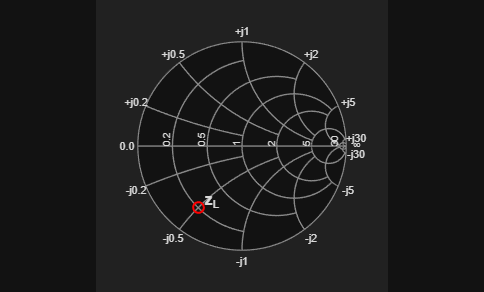


% Optional: Plot on Smith chart
 smithchart_plot(Z0_Q10, ZL_Q10, 'z_L');

## Q11 — Input Impedance with Series Capacitor and TL


fprintf('Q11: TL + Series Capacitor Input Impedance\n');

Q11: TL + Series Capacitor Input Impedance


fprintf('----------------------------\n');

----------------------------


f_Q11 = 5e9;                    % 5 GHz
vp_Q11 = 0.79 * c0;             % Phase velocity
Z0_Q11 = 60;                    % Ω
len_Q11 = 17e-3;                % 17 mm
ZL_Q11 = 25 + 1j*30;            % Ω
C_Q11 = 1e-12;                  % 1 pF

r_Q11 = TLine('series_C', Z0_Q11, ZL_Q11, len_Q11, C_Q11, f_Q11, vp_Q11);


   TL + SERIES CAPACITOR @ 5.00e+09 Hz
  Capacitor: 1.00 pF
  Z_C = 0.0000 -31.8310j Ohm
------------------------------------------
  Z0 = 60.00 Ohm
  ZL = 25.0000 +30.0000j Ohm
  Length = 0.3589 lambda
  Z_TL (TL input) = 21.8591 -20.0823j Ohm
------------------------------------------
  Z_A = Z_C + Z_TL
  Z_A = 21.8591 -51.9132j Ohm
  |Z_A| = 56.33 Ohm
  angle(Z_A) = -67.17 deg



fprintf('✓ Answer: Z_A = %.1f Ω ∠ %.1f°\n\n', abs(r_Q11.Z_A), rad2deg(angle(r_Q11.Z_A)));

✓ Answer: Z_A = 56.3 Ω ∠ -67.2°



## Q12 — Realizing j30 Ω Using Short-Circuited Stub


fprintf('Q12: Short-Circuited Stub to Realize j30 Ω\n');

Q12: Short-Circuited Stub to Realize j30 Ω


fprintf('----------------------------\n');

----------------------------


Z_target_Q12 = 1j*30;
Z0_stub_Q12 = 75;
r_Q12 = TLine('stub', Z_target_Q12, Z0_stub_Q12, 'short');


         STUB DESIGN
  Target Z = j30.0000 Ohm
  Stub Z0 = 75.00 Ohm
------------------------------------------
  SHORT-CIRCUITED STUB:
    tan(βℓ) = 30.0000 / 75.00 = 0.400000
    βℓ = 0.3805 rad = 21.80°
    ℓ = 0.0606 λ  (or 0.5606 λ)
    Verify: Z_in = j·75.00·tan(0.3805) = j30.0000 Ohm ✓
------------------------------------------



fprintf('✓ Answer: ℓ = %.4f λ\n\n', r_Q12.short.len_lambda);

✓ Answer: ℓ = 0.0606 λ



## Q13 & Q14 — Finding Γ_L and Z_L from Γ_A


fprintf('Q13-Q14: Find Load from Input Measurement\n');

Q13-Q14: Find Load from Input Measurement


fprintf('----------------------------\n');

----------------------------


Gamma_A_Q13 = 0.539 * exp(1j * deg2rad(166));
Z0_Q13 = 75;
len_Q13 = 0.3;  % λ
r_Q13 = TLine('load', Z0_Q13, Gamma_A_Q13, len_Q13);


   FIND LOAD FROM INPUT (Q13/Q14 type)
  Z0 = 75.00 Ohm
  Gamma_in = -0.5230 +0.1304j
  |Gamma_in| = 0.5390, angle = 166.00 deg
  Length = 0.3000 lambda
------------------------------------------
  Phase shift: +2βℓ = +2·2π·0.3000 = 216.00 deg
------------------------------------------
  Gamma_L = Gamma_in · exp(+j·216.00°)
  Gamma_L = 0.4998 +0.2019j
  |Gamma_L| = 0.5390, angle = 22.00 deg
------------------------------------------
  Z_L = Z0·(1+Gamma_L)/(1-Gamma_L)
  Z_L = 182.8449 +104.0728j Ohm
  |Z_L| = 210.39 Ohm, angle = 29.65 deg
------------------------------------------
  VSWR = 3.3384



fprintf('✓ Q13 Answer: Γ_L = %.3f ∠ %.0f°\n', abs(r_Q13.Gamma_L), rad2deg(angle(r_Q13.Gamma_L)));

✓ Q13 Answer: Γ_L = 0.539 ∠ 22°


fprintf('✓ Q14 Answer: Z_L = %.0f + j%.0f Ω\n\n', real(r_Q13.Z_L), imag(r_Q13.Z_L));

✓ Q14 Answer: Z_L = 183 + j104 Ω



## Q15-Q17 — Stub Matching Design


fprintf('Q15-Q17: Single-Stub Matching\n');

Q15-Q17: Single-Stub Matching


fprintf('----------------------------\n');

----------------------------


f_Q15 = 1550e6;                 % 1550 MHz
eps_r_Q15 = 2.1;
Z0_Q15 = 75;                    % Ω
ZL_Q15 = 142 + 1j*42.5;         % Ω

% Q15: Calculate wavelength
lambda_Q15 = c0 / (f_Q15 * sqrt(eps_r_Q15));
fprintf('Q15 Answer: λ = %.2f cm\n', lambda_Q15*100);

Q15 Answer: λ = 13.35 cm



% Q16 & Q17: Stub matching
r_Q15 = StubMatch(ZL_Q15, Z0_Q15, 'short', lambda_Q15);


      SINGLE-STUB MATCHING (Q15-Q17)     
  Load: ZL = 142.00 +42.50j Ω
  Line: Z0 = 75 Ω (SHORT stub)
  λ = 13.35 cm
------------------------------------------
  SOLUTION 1:
    d = 0.1839 λ = 24.54 mm  ← Q16
    ℓ = 0.1457 λ = 19.44 mm  ← Q17
  SOLUTION 2:
    d = 0.3755 λ = 50.12 mm
    ℓ = 0.3543 λ = 47.29 mm
------------------------------------------
  ✓ Matched (y = 1.001)



fprintf('✓ Q16 Answer: d = %.2f mm\n', r_Q15.d_mm);

✓ Q16 Answer: d = 24.54 mm


fprintf('✓ Q17 Answer: ℓ = %.2f mm\n\n', r_Q15.l_mm);

✓ Q17 Answer: ℓ = 19.44 mm




%% =========================================================================

%  PLANE WAVE PROBLEMS
%% =========================================================================


## Q21 — Frequency of Plane Wave


fprintf('Q21: Frequency from Phase Term\n');

Q21: Frequency from Phase Term


fprintf('----------------------------\n');

----------------------------


% From phase term: ωt + (4y - 2x - 2z)
% β·r = -4y + 2x + 2z → β = (2, -4, 2) rad/m
beta_vec_Q21 = [2; -4; 2];
beta_mag_Q21 = norm(beta_vec_Q21);
omega_Q21 = beta_mag_Q21 * c0;
freq_Q21 = omega_Q21 / (2*pi);

fprintf('β = [%.0f, %.0f, %.0f] rad/m\n', beta_vec_Q21);

β = [2, -4, 2] rad/m


fprintf('|β| = √24 = %.4f rad/m\n', beta_mag_Q21);

|β| = √24 = 4.8990 rad/m


fprintf('ω = β·c₀ = %.4e rad/s\n', omega_Q21);

ω = β·c₀ = 1.4687e+09 rad/s


fprintf('✓ Answer: f = %.0f MHz\n\n', freq_Q21/1e6);

✓ Answer: f = 234 MHz



## Q22-Q23 — H-Field Phasor and Poynting Vector


fprintf('Q22-Q23: Magnetic Field and Poynting Vector\n');

Q22-Q23: Magnetic Field and Poynting Vector


fprintf('----------------------------\n');

----------------------------


a_Q22 = [2; 1; 0];              % cos coefficient
b_Q22 = [0; -1; -2];            % sin coefficient  
E0_Q22 = 10;                    % V/m
beta_vec_Q22 = [2; -4; 2];      % rad/m

r_Q22 = poynting_pw('time', a_Q22, b_Q22, E0_Q22, beta_vec_Q22);


   PLANE WAVE: H-FIELD & POYNTING (Q22-Q23)
  Ẽ₀ = [20.0+0.0j; 10.0+10.0j; 0.0+20.0j] V/m
  k̂ = [0.4082, -0.8165, 0.4082]
  η = 377 Ω
------------------------------------------
  Q22: H̃₀ = (1/η)·k̂ × Ẽ₀
  H̃₀ = [-10.83-54.14j; 21.66-21.66j; 54.14+10.83j] mA/m
------------------------------------------
  Q23: S̄ = ½·Re{Ẽ × H̃*}
  S̄ = [0.541; -1.083; 0.541] W/m²
  |S̄| = 1.326 W/m²




fprintf('✓ Q22 Answer: H̃₀ = [%.1f%+.1fj; %.1f%+.1fj; %.1f%+.1fj] mA/m\n', ...
    real(r_Q22.H_phasor(1))*1e3, imag(r_Q22.H_phasor(1))*1e3, ...
    real(r_Q22.H_phasor(2))*1e3, imag(r_Q22.H_phasor(2))*1e3, ...
    real(r_Q22.H_phasor(3))*1e3, imag(r_Q22.H_phasor(3))*1e3);

✓ Q22 Answer: H̃₀ = [-10.8-54.1j; 21.7-21.7j; 54.1+10.8j] mA/m


fprintf('✓ Q23 Answer: S̄ = [%.3f; %.3f; %.3f] W/m²\n\n', ...
    r_Q22.S_avg(1), r_Q22.S_avg(2), r_Q22.S_avg(3));

✓ Q23 Answer: S̄ = [0.541; -1.083; 0.541] W/m²



## Q24 — Incident Power on Circular Surface


fprintf('Q24: Power Incident on Circular Surface\n');

Q24: Power Incident on Circular Surface


fprintf('----------------------------\n');

----------------------------


% Using results from Q22-Q23
S_avg_Q24 = r_Q22.S_avg;
D_Q24 = 1;                          % Diameter [m]
A_Q24 = pi * (D_Q24/2)^2;           % Area = π/4 m²
n_hat_Q24 = [1; 0; 1] / sqrt(2);    % Surface normal (unit vector)

S_dot_n_Q24 = dot(S_avg_Q24, n_hat_Q24);
P_incident_Q24 = abs(S_dot_n_Q24) * A_Q24;

fprintf('Surface area A = π/4 = %.4f m²\n', A_Q24);

Surface area A = π/4 = 0.7854 m²


fprintf('S̄·n̂ = %.4f W/m²\n', S_dot_n_Q24);

S̄·n̂ = 0.7657 W/m²


fprintf('✓ Answer: P = |S̄·n̂|·A = %.3f W\n\n', P_incident_Q24);

✓ Answer: P = |S̄·n̂|·A = 0.601 W




%% =========================================================================
%  MATERIAL & WAVE PROPAGATION PROBLEMS
%% =========================================================================


## Q25 — Skin Depth for Shielding


fprintf('Q25: Minimum Coating Thickness (Skin Depth)\n');

Q25: Minimum Coating Thickness (Skin Depth)


fprintf('----------------------------\n');

----------------------------


sigma_Q25 = 58e6;               % 58 MS/m (copper)
f_max_Q25 = 18e9;               % 18 GHz (worst case)

r_Q25 = Medium('skin', sigma_Q25, f_max_Q25);


=== Skin Depth ===
  sigma = 5.800e+07 S/m
  freq = 1.800e+10 Hz
  mu_r = 1.00
  -----------------
  delta = 4.9257e-07 m
  delta = 0.4926 um
  delta = 0.0005 mm



t_min_Q25 = 5 * r_Q25.skin_depth;   % Rule of thumb: t > 5δ

fprintf('At %.0f GHz: δ = %.3f μm\n', f_max_Q25/1e9, r_Q25.skin_depth*1e6);

At 18 GHz: δ = 0.493 μm


fprintf('✓ Answer: t_c > 5δ = %.2f μm\n\n', t_min_Q25*1e6);

✓ Answer: t_c > 5δ = 2.46 μm



## Q26 — Material Classification


fprintf('Q26: Material Classification (Loss Tangent)\n');

Q26: Material Classification (Loss Tangent)


fprintf('----------------------------\n');

----------------------------


eps_r_Q26 = 8;
sigma_Q26 = 0.01;               % S/m
f_Q26 = 5e9;                    % 5 GHz

r_Q26 = Medium(eps_r_Q26, sigma_Q26, f_Q26, 1, 'Q26 Material');


  Q26 MATERIAL @ 5.00e+09 Hz
  Properties:
    eps_r = 8.0000
    mu_r  = 1.0000
    sigma = 1.000e-02 S/m
------------------------------------------
  Classification:
    tan(delta) = 4.494e-03
    Type: Lossless (approx)
------------------------------------------
  Wave Parameters:
    alpha = 6.6597e-01 Np/m
    beta  = 2.9640e+02 rad/m
    lambda = 2.1198e-02 m
    u_p = 1.0599e+08 m/s
    n = 2.8284
------------------------------------------
  Intrinsic Impedance:
    eta = 133.1933 +0.2993j Ohm
    |eta| = 133.1936 Ohm
    angle(eta) = 0.13 deg
------------------------------------------
  Attenuation:
    Skin depth = 1.5016e+00 m
    Loss @ 1m = 5.78 dB



fprintf('tan(δ) = %.4e\n', r_Q26.tan_delta);

tan(δ) = 4.4938e-03


fprintf('✓ Answer: %s\n\n', r_Q26.classification);

✓ Answer: Lossless (approx)



## Q27 — Wave Parameters in Material


fprintf('Q27: Wave Parameters (from Q26)\n');

Q27: Wave Parameters (from Q26)


fprintf('----------------------------\n');

----------------------------


fprintf('α = %.4f Np/m\n', r_Q26.alpha);

α = 0.6660 Np/m


fprintf('β = %.4f rad/m\n', r_Q26.beta);

β = 296.3980 rad/m


fprintf('λ = %.2f cm\n', r_Q26.lambda*100);

λ = 2.12 cm


fprintf('✓ η = %.2f %+.2fj Ω\n\n', real(r_Q26.eta), imag(r_Q26.eta));

✓ η = 133.19 +0.30j Ω




%% =========================================================================
%  INTERFACE & REFLECTION PROBLEMS
%% =========================================================================


## Q28 — Polarization of Incident Wave


fprintf('Q28: Wave Polarization\n');

Q28: Wave Polarization


fprintf('----------------------------\n');

----------------------------


E0_Q28 = 5;  % V/m
E_phasor_Q28 = E0_Q28 * [1; sqrt(3); 2j];
k_hat_Q28 = [1; 0; 0];  % Propagating in +x direction

r_Q28 = Polarization(E_phasor_Q28, k_hat_Q28);


       POLARIZATION ANALYSIS           
  Type:        Circular
  Handedness:  RHCP
----------------------------------------
  Axial Ratio: 1.1547 (1.25 dB)
  Major axis:  10.0000
  Minor axis:  8.6603
  Tilt angle:  90.00 deg
----------------------------------------
  Phasor F:
    Fx = 5.0000
    Fy = 8.6603
    Fz = j10.0000
  k_hat = [1.00, 0.00, 0.00]



fprintf('Type: %s\n', r_Q28.type);

Type: Circular


fprintf('Handedness: %s\n', r_Q28.handedness);

Handedness: RHCP


fprintf('✓ Answer: %s, %s\n', r_Q28.type, r_Q28.handedness);

✓ Answer: Circular, RHCP


fprintf('  Axial Ratio: %.2f (%.1f dB)\n\n', r_Q28.AR, r_Q28.AR_dB);

  Axial Ratio: 1.15 (1.2 dB)



## Q29-Q30 — Angle of Incidence and Transmission


fprintf('Q29-Q30: Incidence and Transmission Angles\n');

Q29-Q30: Incidence and Transmission Angles


fprintf('----------------------------\n');

----------------------------


beta0_Q29 = 20.94;  % rad/m
beta_Q29 = beta0_Q29 * [sqrt(3)/2; -1/2; 0];
n_interface_Q29 = [1; 0; 0];    % Interface normal (yz-plane)

% Q29: Angle of incidence
cos_theta_i_Q29 = dot(beta_Q29, n_interface_Q29) / norm(beta_Q29);
theta_i_Q29 = acosd(cos_theta_i_Q29);
fprintf('✓ Q29 Answer: θ_i = %.1f°\n', theta_i_Q29);

✓ Q29 Answer: θ_i = 30.0°



% Q30: Transmission angle
eps_r1_Q30 = 1;     % Air
eps_r2_Q30 = 4;     % Medium
n1_Q30 = sqrt(eps_r1_Q30);
n2_Q30 = sqrt(eps_r2_Q30);

r_Q30 = Fresnel('snell', n1_Q30, n2_Q30, theta_i_Q29);


=== Snell's Law ===
  n1 = 1.0000, n2 = 2.0000
  theta_i = 30.00 deg
  theta_t = 14.48 deg



fprintf('✓ Q30 Answer: θ_t = %.1f°\n\n', r_Q30.theta_t);

✓ Q30 Answer: θ_t = 14.5°



## Q32 — Reflected Power Fraction


fprintf('Q32: Reflected Power (Oblique Incidence)\n');

Q32: Reflected Power (Oblique Incidence)


fprintf('----------------------------\n');

----------------------------


r_Q32 = Fresnel(eps_r1_Q30, eps_r2_Q30, theta_i_Q29);


     FRESNEL: OBLIQUE INCIDENCE          
  Medium 1: eps_r = 1.000, n = 1.0000
  Medium 2: eps_r = 4.000, n = 2.0000
------------------------------------------
  theta_i = 30.00 deg
  theta_t = 14.48 deg (Snell's law)
  theta_Brewster = 63.43 deg
------------------------------------------
  TE (s-pol, E perpendicular to plane):
    Gamma_TE = -0.3820 +0.0000j
    |Gamma_TE| = 0.3820
    R_TE = 0.1459, T_TE = 0.8541
  TM (p-pol, E parallel to plane):
    Gamma_TM = -0.2829 +0.0000j
    |Gamma_TM| = 0.2829
    R_TM = 0.0800, T_TM = 0.9200



fprintf('TE mode: Γ_TE = %.4f, R_TE = %.2f%%\n', r_Q32.Gamma_TE, r_Q32.R_TE*100);

TE mode: Γ_TE = -0.3820, R_TE = 14.59%


fprintf('TM mode: Γ_TM = %.4f, R_TM = %.2f%%\n', r_Q32.Gamma_TM, r_Q32.R_TM*100);

TM mode: Γ_TM = -0.2829, R_TM = 8.00%


fprintf('✓ Answer: Depends on polarization mix\n');

✓ Answer: Depends on polarization mix


fprintf('  (For mixed polarization, weight by power in each component)\n\n');

  (For mixed polarization, weight by power in each component)



## Q33 — Brewster Angle


fprintf('Q33: Brewster Angle\n');

Q33: Brewster Angle


fprintf('----------------------------\n');

----------------------------


r_Q33 = Fresnel('brewster', eps_r1_Q30, eps_r2_Q30);


=== Brewster Angle ===
  n1 = 1.0000, n2 = 2.0000
  theta_B = 63.4349 deg
  At this angle: Gamma_TM = 0 (no TM reflection)



fprintf('Brewster angle: θ_B = %.1f°\n', r_Q33.theta_Brewster);

Brewster angle: θ_B = 63.4°


fprintf('✓ Answer: %.1f° (TM mode only)\n', r_Q33.theta_Brewster);

✓ Answer: 63.4° (TM mode only)


fprintf('  Note: Mixed polarization means TE component always reflects\n');

  Note: Mixed polarization means TE component always reflects


fprintf('  → No complete zero-reflection angle exists\n\n');

  → No complete zero-reflection angle exists




%% =========================================================================
%  CIRCUIT ELEMENTS PROBLEMS
%% =========================================================================


## Q34-Q35 — Coaxial Capacitor


fprintf('Q34-Q35: Coaxial Capacitor\n');

Q34-Q35: Coaxial Capacitor


fprintf('----------------------------\n');

----------------------------


a_Q34 = 0.5e-2;     % Inner radius: 0.5 cm
b_Q34 = 2.5e-2;     % Outer radius: 2.5 cm
L_Q34 = 10e-2;      % Length: 10 cm
eps_r_Q34 = 4.20;
V_Q34 = 12;         % Voltage

% Q34: Capacitance
eps_Q34 = eps_r_Q34 * eps0;
C_Q34 = 2*pi*eps_Q34*L_Q34 / log(b_Q34/a_Q34);
fprintf('✓ Q34 Answer: C = %.2f pF\n', C_Q34*1e12);

✓ Q34 Answer: C = 14.52 pF



% Q35: Energy stored
W_Q35 = 0.5 * C_Q34 * V_Q34^2;
fprintf('✓ Q35 Answer: W = ½CV² = %.2f pJ\n\n', W_Q35*1e12);

✓ Q35 Answer: W = ½CV² = 1045.29 pJ



## Q36-Q37 — Solenoid Current and Inductance


fprintf('Q36-Q37: Solenoid\n');

Q36-Q37: Solenoid


fprintf('----------------------------\n');

----------------------------


N_Q36 = 200;            % Number of turns
L_sol_Q36 = 10e-2;      % Length: 10 cm
d_Q36 = 1.3e-2;         % Diameter: 1.3 cm
B_Q36 = 6.28e-3;        % Measured B: 6.28 mT

% Q36: Current from B = μ₀·n·I
n_Q36 = N_Q36 / L_sol_Q36;          % Turns per meter
I_Q36 = B_Q36 / (mu0 * n_Q36);
fprintf('✓ Q36 Answer: I = %.2f A\n', I_Q36);

✓ Q36 Answer: I = 2.50 A



% Q37: Inductance L = μ₀·N²·A/ℓ
A_sol_Q37 = pi * (d_Q36/2)^2;
L_ind_Q37 = mu0 * N_Q36^2 * A_sol_Q37 / L_sol_Q36;
fprintf('✓ Q37 Answer: L = %.2f μH\n\n', L_ind_Q37*1e6);

✓ Q37 Answer: L = 66.72 μH




%% =========================================================================
%  SUMMARY OF ANSWERS
%% =========================================================================


fprintf('\n========================================\n');

fprintf('  QUICK ANSWER SUMMARY\n');

  QUICK ANSWER SUMMARY


fprintf('========================================\n\n');


fprintf('TRANSMISSION LINES:\n');

TRANSMISSION LINES:


fprintf('  Q4:  VSWR = %.2f\n', VSWR_Q4);

  Q4:  VSWR = 2.00


fprintf('  Q5:  P_reflected = %.0f%%\n', P_reflected_Q5*100);

  Q5:  P_reflected = 9%


fprintf('  Q6:  Γ = -1\n');

  Q6:  Γ = -1


fprintf('  Q10: zL = 0.2 - j0.5\n');

  Q10: zL = 0.2 - j0.5


fprintf('  Q11: Z_A = %.1f Ω ∠ %.1f°\n', abs(r_Q11.Z_A), rad2deg(angle(r_Q11.Z_A)));

  Q11: Z_A = 56.3 Ω ∠ -67.2°


fprintf('  Q12: ℓ = %.4f λ\n', r_Q12.short.len_lambda);

  Q12: ℓ = 0.0606 λ


fprintf('  Q13: Γ_L = %.3f ∠ %.0f°\n', abs(r_Q13.Gamma_L), rad2deg(angle(r_Q13.Gamma_L)));

  Q13: Γ_L = 0.539 ∠ 22°


fprintf('  Q14: Z_L = %.0f + j%.0f Ω\n', real(r_Q13.Z_L), imag(r_Q13.Z_L));

  Q14: Z_L = 183 + j104 Ω


fprintf('  Q15: λ = %.2f cm\n', lambda_Q15*100);

  Q15: λ = 13.35 cm


fprintf('  Q16: d = %.2f mm\n', r_Q15.d_mm);

  Q16: d = 24.54 mm


fprintf('  Q17: ℓ = %.2f mm\n\n', r_Q15.l_mm);

  Q17: ℓ = 19.44 mm




fprintf('PLANE WAVES:\n');

PLANE WAVES:


fprintf('  Q21: f = %.0f MHz\n', freq_Q21/1e6);

  Q21: f = 234 MHz


fprintf('  Q22: H̃₀ = [%.1f%+.1fj; %.1f%+.1fj; %.1f%+.1fj] mA/m\n', ...
    real(r_Q22.H_phasor(1))*1e3, imag(r_Q22.H_phasor(1))*1e3, ...
    real(r_Q22.H_phasor(2))*1e3, imag(r_Q22.H_phasor(2))*1e3, ...
    real(r_Q22.H_phasor(3))*1e3, imag(r_Q22.H_phasor(3))*1e3);

  Q22: H̃₀ = [-10.8-54.1j; 21.7-21.7j; 54.1+10.8j] mA/m


fprintf('  Q23: S̄ = [%.3f; %.3f; %.3f] W/m²\n', ...
    r_Q22.S_avg(1), r_Q22.S_avg(2), r_Q22.S_avg(3));

  Q23: S̄ = [0.541; -1.083; 0.541] W/m²


fprintf('  Q24: P = %.3f W\n\n', P_incident_Q24);

  Q24: P = 0.601 W




fprintf('MATERIALS:\n');

MATERIALS:


fprintf('  Q25: t_c > %.2f μm\n', t_min_Q25*1e6);

  Q25: t_c > 2.46 μm


fprintf('  Q26: %s\n', r_Q26.classification);

  Q26: Lossless (approx)


fprintf('  Q27: η = %.2f %+.2fj Ω\n\n', real(r_Q26.eta), imag(r_Q26.eta));

  Q27: η = 133.19 +0.30j Ω




fprintf('INTERFACES:\n');

INTERFACES:


fprintf('  Q28: %s, %s\n', r_Q28.type, r_Q28.handedness);

  Q28: Circular, RHCP


fprintf('  Q29: θ_i = %.1f°\n', theta_i_Q29);

  Q29: θ_i = 30.0°


fprintf('  Q30: θ_t = %.1f°\n', r_Q30.theta_t);

  Q30: θ_t = 14.5°


fprintf('  Q32: See mixed polarization calculation\n');

  Q32: See mixed polarization calculation


fprintf('  Q33: θ_B = %.1f° (TM only)\n\n', r_Q33.theta_Brewster);

  Q33: θ_B = 63.4° (TM only)




fprintf('CIRCUITS:\n');

CIRCUITS:


fprintf('  Q34: C = %.2f pF\n', C_Q34*1e12);

  Q34: C = 14.52 pF


fprintf('  Q35: W = %.2f pJ\n', W_Q35*1e12);

  Q35: W = 1045.29 pJ


fprintf('  Q36: I = %.2f A\n', I_Q36);

  Q36: I = 2.50 A


fprintf('  Q37: L = %.2f μH\n\n', L_ind_Q37*1e6);

  Q37: L = 66.72 μH




fprintf('========================================\n');

fprintf('  END OF E23 SOLUTIONS\n');

  END OF E23 SOLUTIONS


fprintf('========================================\n');